%paralel 4
clear variables

syms R L C s
A=[0 -1/L;1/C -1/R*C];
b=[1/L; 0];
c=[0 1];
d=0;
H=c*inv(s*eye(2)-A)*b+d

$$H = \frac{R}{L\,C^{2}\,s+L\,R\,C\,s^{2}+R}$$

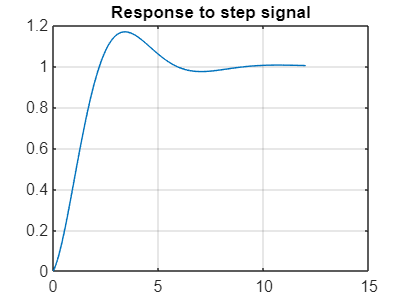


R=1;L=1;C=1;

% declare the state space object by calling ss
sistem=ss([0 -1/L;1/C -1/R*C],[1/L; 0],[0 1],0);
% initial conditions different from zero
x0=[0.2 0];
% time simulation basis
t=0:0.1:12;
% unity step signal as input signal
u=ones(1,length(t));
% step response when calling lsim
[y,t,x]=lsim(sistem,u,t,x0);
plot(t,y);title('Response to step signal');
grid; 

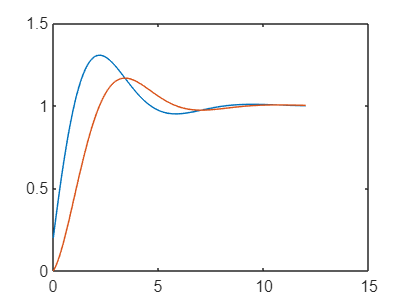

plot(t,x);


%Serie 4
A=[-R/L -1/L;1/C 0];
b=[1/L; 0];
c=[0 1];
d=0;
H=c*inv(s*eye(2)-A)*b+d

$$H = \frac{1}{s^{2}+s+1}$$


R=1;L=1;C=1;

% declare the state space object by calling ss
sistem=ss([-R/L -1/L;1/C 0],[1/L; 0],[0 1],0);
% initial conditions different from zero
x0=[0.2 0];
% time simulation basis
t=0:0.1:12;
% unity step signal as input signal
u=ones(1,length(t));
% step response when calling lsim
[y,t,x]=lsim(sistem,u,t,x0);
plot(t,y);title('Response to step signal');
grid; 

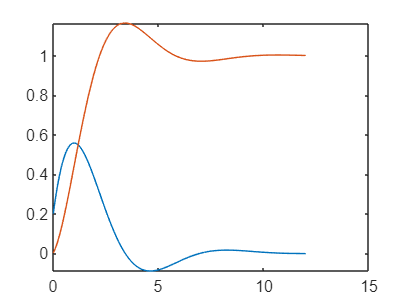

plot(t,x);


%Serie 3
A=[-R/L -1/L;1/C 0];
b=[1/L; 0];
c=[R 0];
d=0;
H=c*inv(s*eye(2)-A)*b+d

$$H = \frac{s}{s^{2}+s+1}$$

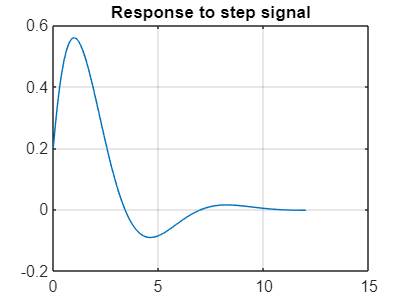


R=1;L=1;C=1;

% declare the state space object by calling ss
sistem=ss([-R/L -1/L;1/C 0],[1/L; 0],[R 0],0);
% initial conditions different from zero
x0=[0.2 0];
% time simulation basis
t=0:0.1:12;
% unity step signal as input signal
u=ones(1,length(t));
% step response when calling lsim
[y,t,x]=lsim(sistem,u,t,x0);
plot(t,y);title('Response to step signal');
grid; 

plot(t,x);



%paralel2
A=[-1/R/C 1/C;-1/L 0];
b=[1/R/C; 1/L];
c=[-1 0];
d=1;
H=c*inv(s*eye(2)-A)*b+d

$$H = 1-\frac{s}{s^{2}+s+1}-\frac{1}{s^{2}+s+1}$$

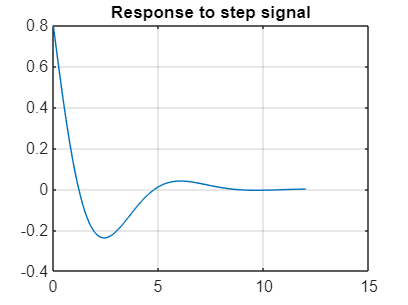


R=1;L=1;C=1;

% declare the state space object by calling ss
sistem=ss([-1/R/C 1/C;-1/L 0],[1/R/C; 1/L],[-1 0],1);
% initial conditions different from zero
x0=[0.2 0];
% time simulation basis
t=0:0.1:12;
% unity step signal as input signal
u=ones(1,length(t));
% step response when calling lsim
[y,t,x]=lsim(sistem,u,t,x0);
plot(t,y);title('Response to step signal');
grid; 

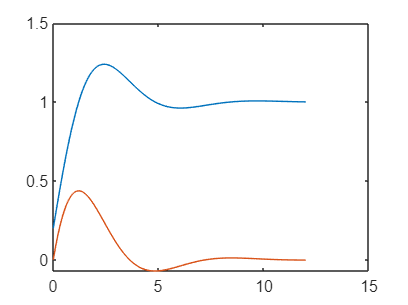

plot(t,x);